# 资本资产定价模型

CAPM模型的公式是:


$$E\left(r_i \right)=r_f +\beta \;\left(r_M -r_f \right)$$



$$\beta_{\mathrm{im}} =\frac{\mathrm{Cov}\left(r_i ,r_m \right)}{\mathrm{Var}\left(r_m \right)}=\frac{\mathrm{Cov}\left(r_i ,r_m \right)}{\mathrm{std}\left(r_m \right)\mathrm{std}\left(r_i \right)}\cdot \frac{\mathrm{std}\left(r_i \right)}{\mathrm{std}\left(r_M \right)}=\mathrm{corr}\left(r_i ,r_m \right)\cdot \frac{\mathrm{std}\left(r_i \right)}{\mathrm{std}\left(r_M \right)}$$


本节将利用CAPM模型, 通过$\beta \;$值和股票市场收益率, 估计股票月收益率, 且与真实值比较.

[字段解释]

Stkcd: 股票代码 (选择2001年行业分类标准中的能源行业, 删除数据库无法下载的, 和收益率与$\beta \;$值不对齐的股票)

Trdmnt: 交易月份 (2016年)

Betaval: 股票每个月的$\beta \;$值 (CSMAR数据库中只有2013~2016年)

Idxrtn: 中证细分能源产业主题指数每个月的回报率

Mretwd: 股票每个月的收益率 (现金股利再投资)

clear
close all
clc

从CSMAR数据库查到2016年银行一年期储蓄存款的利率$r_f =1\ldotp 5%$, 作为无风险利率.

r_f = 0.015;

读数据.

data = readtable("BETA_Mbeta1.xlsx");

估计股票的月收益率.

rtn_1 = (data.Idxrtn - r_f) .* data.Betaval + r_f;

与真实的$\beta \;$比较.

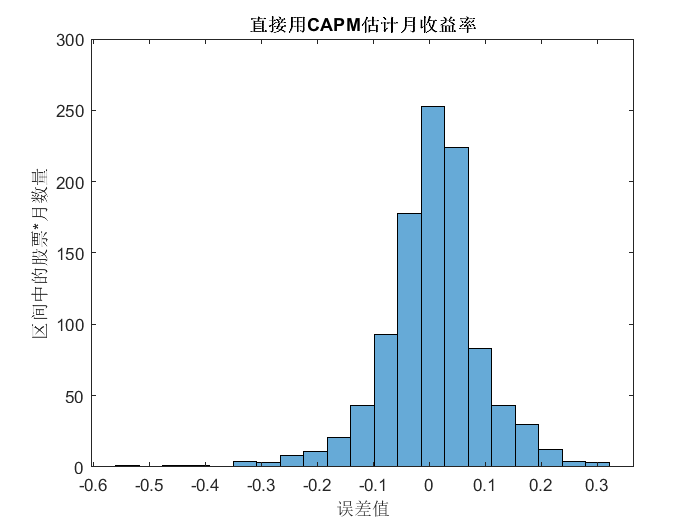

histogram(rtn_1 - data.Mretwd, 'NumBins', 21)
xlabel('误差值')
ylabel('区间中的股票*月数量')
title('直接用CAPM估计月收益率')

可以看到误差较大, 接下来用$\beta \;$值和指数收益率, 对股票的月收益率做回归.

model = fitlm([data.Betaval, data.Idxrtn - r_f], data.Mretwd)

model = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE         tStat        pValue   
                   ________    _________    ________    ___________

    (Intercept)    0.018439    0.0096441      1.9119       0.056171
    x1             -0.00142      0.01093    -0.12991        0.89666
    x2               1.4317     0.041105      34.831    2.1331e-175


Number of observations: 1016, Error degrees of freedom: 1013
Root Mean Squared Error: 0.0823
R-squared: 0.545,  Adjusted R-Squared: 0.544
F-statistic vs. constant model: 607, p-value = 5.88e-174

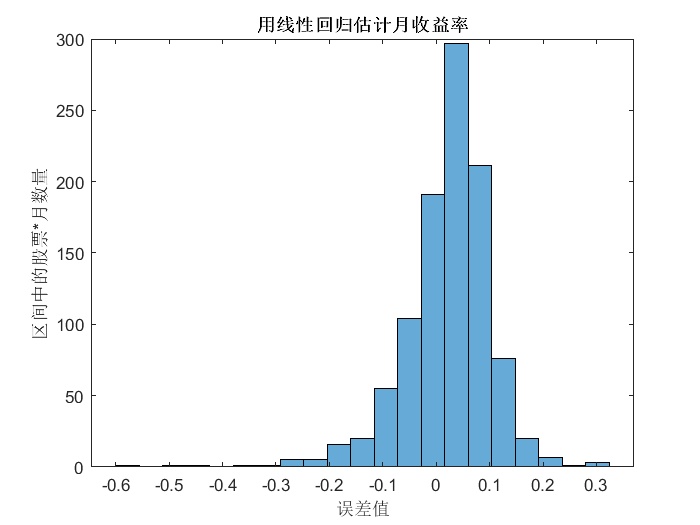

rtn_2 = predict(model, [data.Betaval,data.Idxrtn]);
histogram(rtn_2 - data.Mretwd, 'NumBins', 21)
xlabel('误差值')
ylabel('区间中的股票*月数量')
title('用线性回归估计月收益率')

结果比CAPM模型稍好了一些.

用随机森林模型重新估计.

rfm_1 = fitrensemble([data.Betaval, data.Idxrtn - r_f], data.Mretwd)

rfm_1 =   classreg.learning.regr.RegressionEnsemble
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 1016
               NumTrained: 100
                   Method: 'LSBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}
           Regularization: []


  Properties, Methods


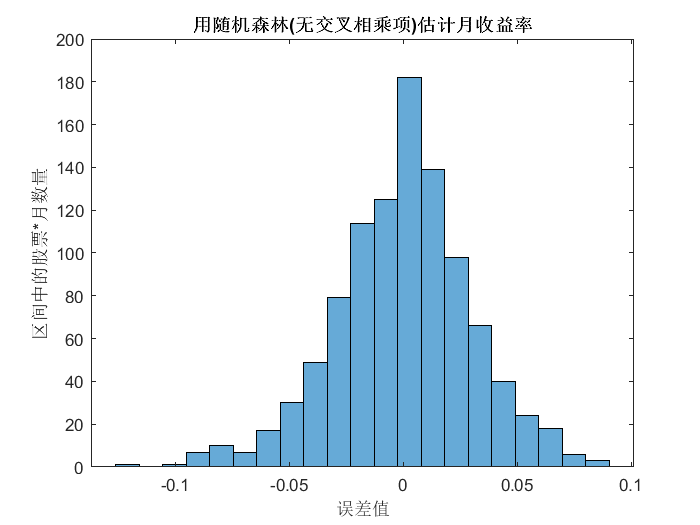

rtn_3 = predict(rfm_1, [data.Betaval, data.Idxrtn - r_f]);
histogram(rtn_3 - data.Mretwd, 'NumBins', 21)
xlabel('误差值')
ylabel('区间中的股票*月数量')
title('用随机森林(无交叉相乘项)估计月收益率')

考虑到CAPM模型中有交叉相乘项, 将其结合进模型中.

rfm_2 = fitrensemble([data.Betaval, data.Idxrtn - r_f, data.Betaval .* (data.Idxrtn - r_f)], data.Mretwd)

rfm_2 =   classreg.learning.regr.RegressionEnsemble
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 1016
               NumTrained: 100
                   Method: 'LSBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}
           Regularization: []


  Properties, Methods


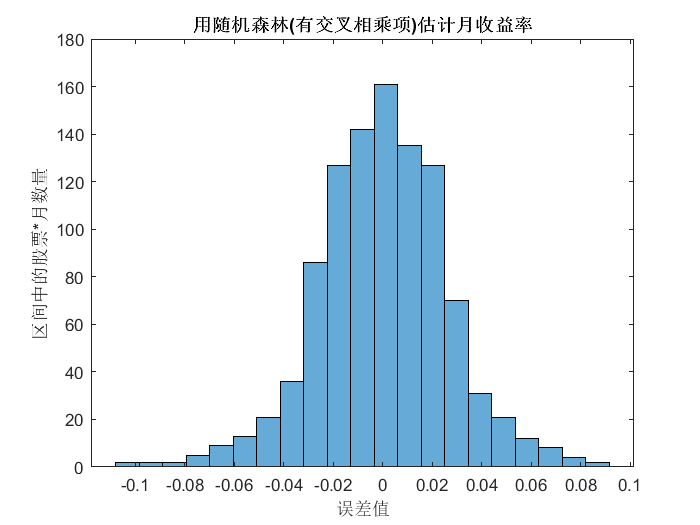

rtn_4 = predict(rfm_2, [data.Betaval, data.Idxrtn - r_f, data.Betaval .* (data.Idxrtn - r_f)]);
histogram(rtn_4 - data.Mretwd, 'NumBins', 21)
xlabel('误差值')
ylabel('区间中的股票*月数量')
title('用随机森林(有交叉相乘项)估计月收益率')